%Ideal resistance curve from datasheet
Deg_C = zeros(201, 1);
 k = -50;
 for a = 1:201;
    Deg_C(a) = k;
    k = k+1;
    a = a+1;
 end

R_t_div_R25 = [66.9745; 62.3986; 58.1649; 54.2458; 50.6159;
                47.2520; 44.1331; 41.2398; 38.5544; 36.0608; 
                33.77440; 31.5905; 29.5877; 27.7243; 25.9897; 
                24.3743; 22.8691; 21.4660; 20.1574; 18.9365; 
                17.7969; 16.7327; 15.7384; 14.8091; 13.9402;
                13.1273; 12.3666; 11.6544; 10.9874; 10.3624; 
                9.7765; 9.2271; 8.7118; 8.2281; 7.7741; 7.3476; 
                6.9470; 6.5704; 6.2164; 5.8834; 5.5700; 5.2751; 
                4.9975; 4.7359; 4.4895; 4.2572; 4.0382; 3.8317; 
                3.6368; 3.4529; 3.2791; 3.1165; 2.9628; 2.8176;
                2.6802; 2.5504; 2.4275; 2.3111; 2.2010; 2.0968; 
                1.9980; 1.9044; 1.8157; 1.7315; 1.6518; 1.5761;
                1.5043; 1.4361; 1.3714; 1.3099; 1.2515; 1.1960;
                1.1432; 1.0931; 1.0454; 1.0000; 0.9568; 0.9157; 
                0.8766; 0.8393; 0.8038; 0.7700; 0.7378; 0.7071; 
                0.6778; 0.6498; 0.6232; 0.5978; 0.5735; 0.5503; 
                0.5282; 0.5071; 0.4869; 0.4677; 0.4492; 0.4316; 
                0.4148; 0.3987; 0.3833; 0.3686; 0.3545; 0.3415; 
                0.3291; 0.3172; 0.3058; 0.2924; 0.2844; 0.2743; 
                0.2646; 0.2554; 0.2465; 0.2379; 0.2297; 0.2219; 
                0.2143; 0.2070; 0.2001; 0.1933; 0.1869; 0.1807; 
                0.1747; 0.1690; 0.1634; 0.1581; 0.1530; 0.1481; 
                0.1433; 0.1388; 0.1344; 0.1301; 0.1261; 0.1221; 
                0.1183; 0.1147; 0.1111; 0.1077; 0.1045; 0.1013; 
                0.0982; 0.0953; 0.0924; 0.0897; 0.0870; 0.0845; 
                0.0820; 0.0796; 0.0773; 0.0751; 0.0729; 0.0708; 
                0.0688; 0.0669; 0.0650; 0.0632; 0.0615; 0.0598; 
                0.0581; 0.0566; 0.0550; 0.0535; 0.0521; 0.0507; 
                0.0494; 0.0481; 0.0468; 0.0456; 0.0444; 0.0433;
                0.0422; 0.0411; 0.0400; 0.0390; 0.0381; 0.0371; 
                0.0362; 0.0353; 0.0344; 0.0336; 0.0328; 0.0320; 
                0.0312; 0.0304; 0.0297; 0.0290; 0.0283; 0.0277;
                0.0270; 0.0264; 0.0258; 0.0252; 0.0246; 0.0240; 
                0.0235; 0.0230; 0.0224; 0.0219; 0.0215; 0.0210; 
                0.0205; 0.0201; 0.0196];

tempcv = table(Deg_C,R_t_div_R25, R_t_div_R25*10000);
tempcv.Properties.VariableNames{3} = 'R_actual';
head(tempcv)

ans = 8×3 table
    Deg_C    R_t_div_R25     R_actual 
    _____    ___________    __________

     -50       66.975       6.6975e+05
     -49       62.399       6.2399e+05
     -48       58.165       5.8165e+05
     -47       54.246       5.4246e+05
     -46       50.616       5.0616e+05
     -45       47.252       4.7252e+05
     -44       44.133       4.4133e+05
     -43        41.24        4.124e+05


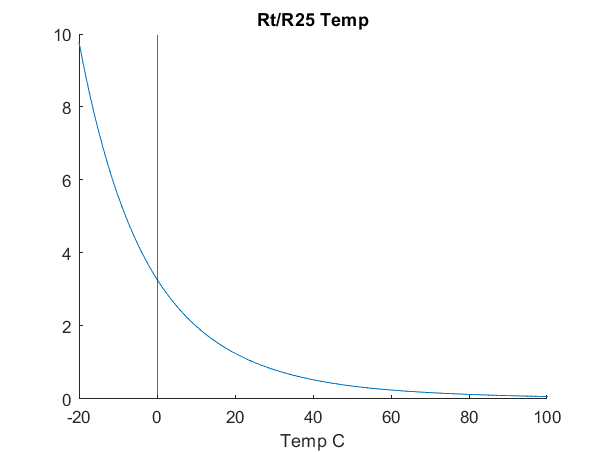

figure
hold on
title("Rt/R25 Temp")
plot(tempcv.Deg_C, tempcv.R_t_div_R25)
xlim([-20 100])
xline(0)
xlabel("Temp C")
hold off

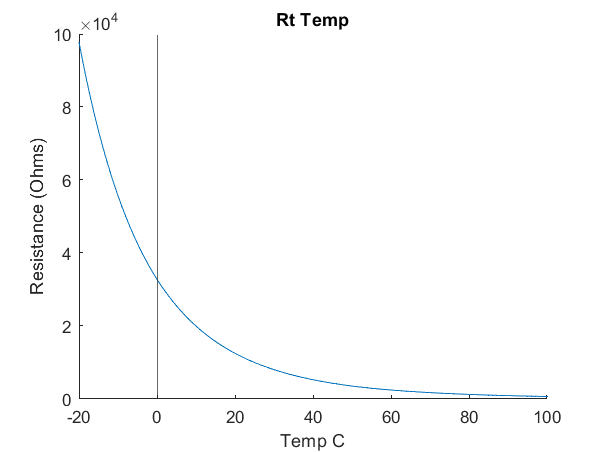

figure
hold on
title("Rt Temp")
plot(tempcv.Deg_C, tempcv.R_actual)
xlim([-20 100])
xline(0)
ylabel("Resistance (Ohms)")
xlabel("Temp C")
hold off

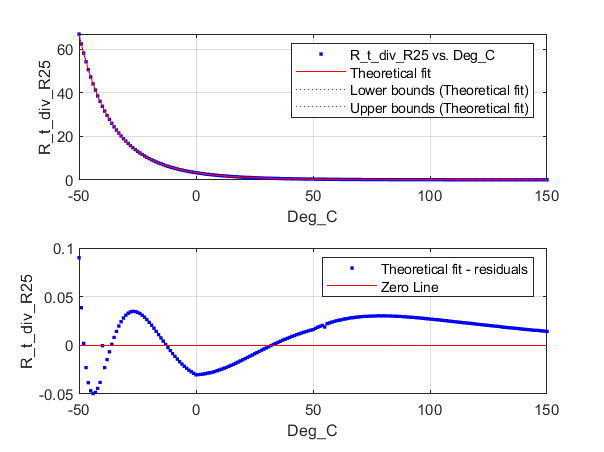

fitresult =      General model Exp2:
     fitresult(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =      0.7498  (0.7158, 0.7838)
       b =    -0.08268  (-0.08327, -0.08209)
       c =        2.56  (2.523, 2.596)
       d =     -0.0412  (-0.04169, -0.0407)

gof = struct with fields:
           sse: 0.1164
       rsquare: 1.0000
           dfe: 197
    adjrsquare: 1.0000
          rmse: 0.0243


[fitresult, gof] = createFit(Deg_C, R_t_div_R25)

function [fitresult, gof] = createFit(Deg_C, R_t_div_R25)
%CREATEFIT(DEG_C,R_T_DIV_R25)
%  Create a fit.
%
%  Data for 'Theoretical fit' fit:
%      X Input: Deg_C from Temperature_vs_Restistance_Curve
%      Y Output: R_t_div_R25 from Temperature_vs_Restistance_Curve
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 16-Oct-2022 23:50:14


%% Fit: 'Theoretical fit'.
[xData, yData] = prepareCurveData( Deg_C, R_t_div_R25 );

% Set up fittype and options.
ft = fittype( 'exp2' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [2.66228343013329 -0.0636046566404981 0.222896542243226 -0.0263516495191541];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Create a figure for the plots.
figure( 'Name', 'Theoretical fit' );

% Plot fit with data.
subplot( 2, 1, 1 );
h = plot( fitresult, xData, yData, 'predobs', 0.99 );
legend( h, 'R_t_div_R25 vs. Deg_C', 'Theoretical fit', 'Lower bounds (Theoretical fit)', 'Upper bounds (Theoretical fit)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Deg_C', 'Interpreter', 'none' );
ylabel( 'R_t_div_R25', 'Interpreter', 'none' );
grid on

% Plot residuals.
subplot( 2, 1, 2 );
h = plot( fitresult, xData, yData, 'residuals' );
legend( h, 'Theoretical fit - residuals', 'Zero Line', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Deg_C', 'Interpreter', 'none' );
ylabel( 'R_t_div_R25', 'Interpreter', 'none' );
grid on

end
